## Figure 1a

%%
%The taxonomic cladogram was generated using the iTOL web tool (http://huttenhower.sph.harvard.edu/galaxy/)
%input data in the ./Figure1a_iTol/

## Figure 1b

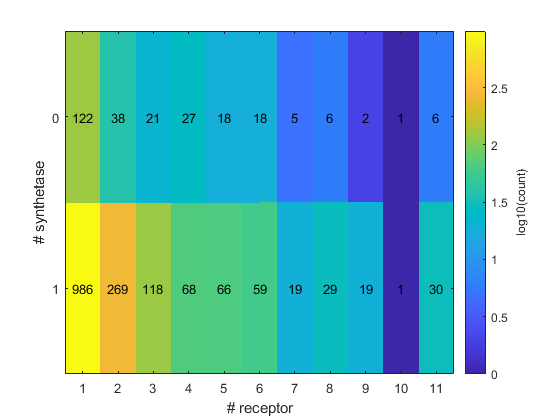

%%

clc;
clear;
load ./data/rec_seqdist_1.mat;
load ./data/rec_seqdist_2.mat;
load ./data/rec_data.mat;
rec.seqdist678910=[rec_seqdist_1;rec_seqdist_2];
load ./data/syn_data.mat;
load ./data/synpepseqdist_pure.mat;
load ./data/recgroup.mat;
load ./data/physeqdist_pure.mat;
load ./data/taxt.mat;
load ./data/rec_seqdist_1_order.mat;
load ./data/rec_seqdist_2_order.mat;
load ./data/rec_order.mat;
rec1989.seqdist678910=[rec_seqdist_1_order;rec_seqdist_2_order];
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
reccount=tabulate(rec.strainnames);
strains=[];
strains.name=reccount(:,1);
strains.reccount=cell2mat(reccount(:,2));
a=ismember(strains.name,syn.strainnames);
strains.syncount=double(a);
% statistics about the sp strain
synlist=min(strains.syncount(:)):max(strains.syncount(:));
reclist=min(strains.reccount(:)):max(strains.reccount(:));
syn_rec_stat=zeros(length(synlist),length(reclist));
for s=1:length(synlist)
    for r=1:length(reclist)
        syn_rec_stat(s,r)=sum(strains.syncount(:)==synlist(s) & strains.reccount(:)==reclist(r));
    end
end
syn_rec_stat_1=zeros(2,11);
syn_rec_stat_1(:,1:10)=syn_rec_stat(:,1:10);
syn_rec_stat_1(1,11)=sum(syn_rec_stat(1,11:end));
syn_rec_stat_1(2,11)=sum(syn_rec_stat(2,11:end));


figure,
imagesc(log10(syn_rec_stat_1));
hold on;
for s=1:length(synlist)
    for r=1:length(reclist(1:11))
        xloc=r;
        yloc=s;
        text(xloc,yloc,num2str(syn_rec_stat_1(s,r)),'HorizontalAlignment', 'center')
    end
end
xticks(reclist)
yticks(synlist+1)
yticklabels(strsplit(num2str(synlist)));
xlabel('# receptor')
ylabel('# synthetase')
ch=colorbar;
ylabel(ch,'log10(count)')

## Figure 1c

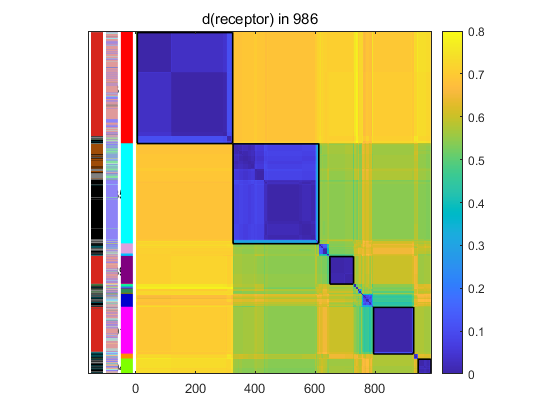

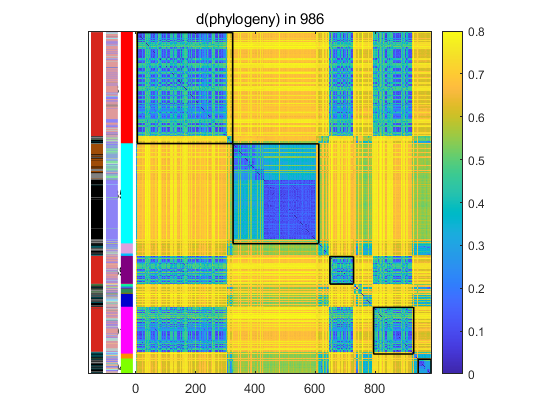

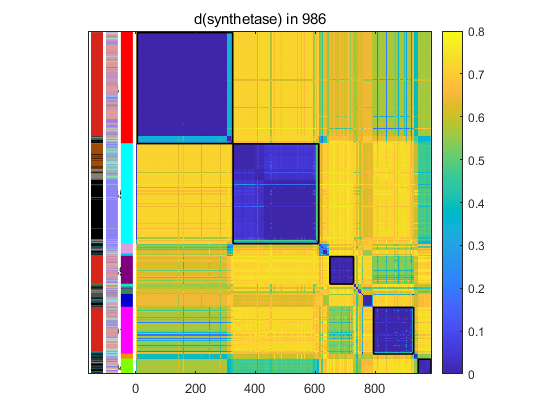

a=find(leaforder_alonesp<987);
leaforder_alonesp_pure=leaforder_alonesp(a);
groupsize_thresh=40;%40
linecolor=0*[0.8,0,0.8];
linewidth=1.2;
distm_rec_986=rec1989.seqdist678910(1:986,1:986);

%作图
figure;


for k=1:3
    figure;
    

    if k==1
        toplotm=distm_rec_986(leaforder_alonesp_pure,leaforder_alonesp_pure);
        titlestr='d(receptor) in 986';
    elseif k==2
        toplotm=physeqdist_pure(leaforder_alonesp_pure,leaforder_alonesp_pure);
         titlestr='d(phylogeny) in 986';
    else
        toplotm=synpepseqdist_pure(leaforder_alonesp_pure,leaforder_alonesp_pure);
         titlestr='d(synthetase) in 986';
    end
    imagesc(toplotm);
    hold on;
    
    groupfreq_pure=tabulate(recgroup(1:986));
    a=find(groupfreq_pure(:,2)>0);
    groupfreq_pure_1=groupfreq_pure(a,:);
    rec986_groupsize=groupfreq_pure_1(:,2);
    [~,recgroup_986_orderbysize]=sort(rec986_groupsize,'descend');
    %addpath '\\192.168.1.150\gsh\20210823_new_begin\Pyoverdine\1_data_summary_last\program';
    
    %colorgroups= min(1,max(0,cbrewer('qual', 'Set1',1+length(a))));
    colorgroups=readtable('./data/colorcode17.xlsx');
    colorgroups=colorgroups(:,3:5);
    colorgroups=table2array(colorgroups);
    %colorgroups=colorgroups(recgroup_986_orderbysize,:);
    
    for i=1:length(a)
        g=a(i);
        colorcode=colorgroups(i,:);
        thisg_members=find(recgroup(leaforder_alonesp_pure)==g);
        if length(thisg_members)>groupsize_thresh

            plot([min(thisg_members),max(thisg_members)],(thisg_members(end)+1)*[1,1],'color',linecolor,'LineWidth',linewidth);
            plot((thisg_members(end)+1)*[1,1],[min(thisg_members),max(thisg_members)],'color',linecolor,'LineWidth',linewidth);

            plot([min(thisg_members),max(thisg_members)],(thisg_members(1)+1)*[1,1],'color',linecolor,'LineWidth',linewidth);
            plot((thisg_members(1)+1)*[1,1],[min(thisg_members),max(thisg_members)],'color',linecolor,'LineWidth',linewidth);

            text(-80, mean(thisg_members),num2str(g));
        end


        ph=patch([-50,-10,-10,-50],[thisg_members(1)-1,thisg_members(1)-1,thisg_members(end),thisg_members(end)],colorcode);
        ph.LineStyle='none';

    end

    
    hold on;
    
    recpure_isolation=taxt.information.Isolation_Source_Gsh_new(1:986);
    number_isolation=zeros(986,1);
    for i=1:986
        if recpure_isolation{i}=="human"
             number_isolation(i,1)=1;
        elseif recpure_isolation(i) =="soil"
             number_isolation(i,1)=2;
        elseif recpure_isolation(i) =="plant"
             number_isolation(i,1)=3;
        elseif recpure_isolation(i) =="water"
             number_isolation(i,1)=4;
    %     elseif rec1106.isolate1(i) =="milk"
    %         number(i,1)=5;
        elseif recpure_isolation(i) =="others"
             number_isolation(i,1)=5;
        elseif recpure_isolation(i) =="unknown"
             number_isolation(i,1)=6;
        end
    end
    colorgroup_isolation=[0.875,0.6055,0.6055;0.9336,0.7374,0.5586;0.5234,0.8828,0.6328;0.5703,0.9648,0.9531;0.50,0.50,0.50;0.5547,0.5156,0.9648];
        
    number_isolation_order=number_isolation(leaforder_alonesp_pure); 
    for i=1:length(number_isolation_order)
        if number_isolation_order(i)==1
            colorcode=colorgroup_isolation(1,:);
        elseif number_isolation_order(i)==2
            colorcode=colorgroup_isolation(2,:);
        elseif number_isolation_order(i)==3
            colorcode=colorgroup_isolation(3,:); 
        elseif number_isolation_order(i)==4
            colorcode=colorgroup_isolation(4,:); 
        elseif number_isolation_order(i)==5
            colorcode=colorgroup_isolation(5,:);
        elseif number_isolation_order(i)==6
            colorcode=colorgroup_isolation(6,:);
        end
        thisg_members=i;
        ph=patch([-100,-60,-60,-100],[thisg_members(1)-1,thisg_members(1)-1,thisg_members(end),thisg_members(end)],colorcode);
        ph.LineStyle='none';
    end
    hold on;
    species_pure=readtable('./data/pure_species.csv');%做figure1a时复制出pure的species信息
    number_species=zeros(986,1);
    for i=1:986
        if species_pure.species{i}=="aeruginosa"
            number_species(i,1)=1;
        elseif species_pure.species{i}=="fluorescens"
            number_species(i,1)=2;
        elseif species_pure.species{i}=="syringae"
            number_species(i,1)=3;
        elseif species_pure.species{i}=="putida"
            number_species(i,1)=4;
        elseif species_pure.species{i}=="sp"
            number_species(i,1)=5;
        elseif species_pure.species{i}=="Others"
            number_species(i,1)=6;
        end
    end
    colorgroup_species=[0.8398,0.1484,0.1094;0.0117,0.4062,0.4453;0.625,0.2969,0.0273;0.2422,0.4609,0.2422;0,0,0;0.5,0.5,0.5];
    number_species_order=number_species(leaforder_alonesp_pure); 
    for i=1:length(number_isolation_order)
        if number_species_order(i)==1
            colorcode=colorgroup_species(1,:);
        elseif number_species_order(i)==2
            colorcode=colorgroup_species(2,:);
        elseif number_species_order(i)==3
            colorcode=colorgroup_species(3,:); 
        elseif number_species_order(i)==4
            colorcode=colorgroup_species(4,:); 
        elseif number_species_order(i)==5
            colorcode=colorgroup_species(5,:);
        elseif number_species_order(i)==6
            colorcode=colorgroup_species(6,:);
        end
        thisg_members=i;
        ph=patch([-150,-110,-110,-150],[thisg_members(1)-1,thisg_members(1)-1,thisg_members(end),thisg_members(end)],colorcode);
        ph.LineStyle='none';
    end
    
    set(gca,'ytick',[])
    xlim([-160,length(leaforder_alonesp_pure)+1])

    title(titlestr)
    colorbar
    caxis([0 0.8])
    

   

    axis square
    
  xx=distm_rec_986(leaforder_alonesp_pure,leaforder_alonesp_pure);
%xx=synpepseqdist_pure(leaforder_alonesp_pure,leaforder_alonesp_pure);
 x=xx(:);
 y=toplotm(:);
 tokeep=(~isnan(x) & ~isnan(y));
 corm=corrcoef(x(tokeep),y(tokeep));
end


%计算相关系数
xx=distm_rec_986(leaforder_alonesp_pure,leaforder_alonesp_pure);
yy=physeqdist_pure(leaforder_alonesp_pure,leaforder_alonesp_pure);  
zz=synpepseqdist_pure(leaforder_alonesp_pure,leaforder_alonesp_pure);
%xx=synpepseqdist_pure(leaforder_alonesp_pure,leaforder_alonesp_pure);
corr2(xx,yy)

ans = 0.5114

corr2(xx,zz)

ans = 0.8800

## Figure 1d

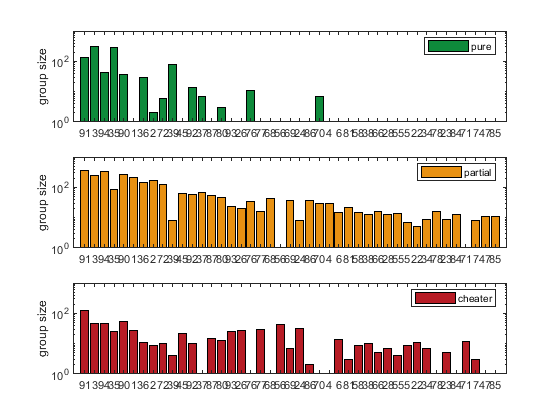

distm_rec=rec.seqdist678910;
if ~exist('./output/groupinfor_feature.mat','file')
    dist_trehs=0.3;%这里确定的经验值是0.3
    disttrehs=dist_trehs;
    
    linkm_rec_new=linkage(distm_rec);
    optleaf_rec_new = optimalleaforder(linkm_rec_new,distm_rec);
    [recgroup_new,totalgnum_new,leaforder_alonesp_new] = Cluster_byconnection(distm_rec,disttrehs,optleaf_rec_new);
    save('./output/groupinfor_feature.mat','linkm_rec_new','optleaf_rec_new','recgroup_new','totalgnum_new','leaforder_alonesp_new');
else
    load('./output/groupinfor_feature.mat');
end

rec.straintype(1:986,1)=1;
cheater1name=find(strcmp(rec.strainnames,taxt.cheater(1)));
rec.straintype(987:(cheater1name(1)-1),1)=2;
rec.straintype(cheater1name(1):rec.datanum,1)=3;


groupsize=zeros(1,totalgnum_new);
group_typebelong=zeros(3,totalgnum_new);
for g=1:totalgnum_new
    members_rec=find(recgroup_new==g);
    members_straintype=rec.straintype(members_rec);
    group_typebelong(:,g)=[sum(members_straintype==1),sum(members_straintype==2),sum(members_straintype==3)];
    thisg_members=find(recgroup_new(leaforder_alonesp_new)==g);
    groupsize(g)=length(thisg_members);
end


[value,order]=sort(groupsize,'descend');
gnumtoshow=find(groupsize(order)>10, 1, 'last' );

figure;
subplot(3,1,1)
gnumtoshow=find(groupsize(order)>10, 1, 'last' );
bar(group_typebelong(1,order(1:gnumtoshow)'),'stacked',"FaceColor","#0E8A3B")
legend({'pure'})
set(gca,'yscale','log')
ylim([1,1000]);
ylabel('group size');
xticks(1:length(order((1:gnumtoshow))))
xticklabels(order((1:gnumtoshow)))
subplot(3,1,2)
gnumtoshow=find(groupsize(order)>10, 1, 'last' );
bar(group_typebelong(2,order(1:gnumtoshow)'),'stacked',"FaceColor","#E89112")
legend({'partial'})
set(gca,'yscale','log')
ylim([1,1000]);
ylabel('group size');
xticks(1:length(order((1:gnumtoshow))))
xticklabels(order((1:gnumtoshow)))
subplot(3,1,3)
gnumtoshow=find(groupsize(order)>10, 1, 'last' );
bar(group_typebelong(3,order(1:gnumtoshow)'),'stacked',"FaceColor","#B71C25")
legend({'cheater'})
set(gca,'yscale','log')
ylim([1,1000]);
ylabel('group size');
xticks(1:length(order((1:gnumtoshow))))
xticklabels(order((1:gnumtoshow)))

## Figure S1a

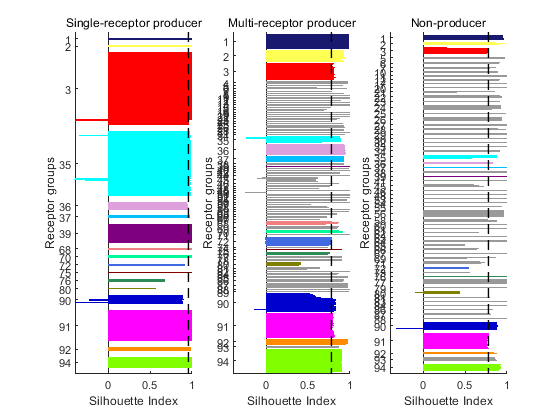

figure;
subplot(1,3,1)
a=ismember(rec1989.sptypeid,1);
recgroup_pure=recgroup(a);
seqdist_pure=rec1989.seqdist678910(a,a);
s_pure=silhouette(seqdist_pure,recgroup_pure);
[b,c]=sort(recgroup_pure);
s_pure_order=s_pure(c);
d=tabulate(b);
f=find(d(:,2)~=0);
len1=d(:,2);
len=len1(f);
recg1=d(:,1);
recg=recg1(f);
colorgroups_1=readtable('./data/colorcode17.xlsx');
colorgroups=colorgroups_1(:,3:5);
colorgroups=table2array(colorgroups);

hold on
num=30;
tick=zeros(length(len),1);
for i=1:length(len)
    recgtemp=recg(i);
    colorcode=colorgroups(i,:);

    g=find(ismember(b,recgtemp));
    gnum=length(g);
    s_pure_order_group=s_pure_order(g);
    
  
    tick(i)=num+(gnum+1)/2;

    barh((num+1):(num+gnum),s_pure_order_group,'Facecolor',colorgroups(i,:),'EdgeColor',colorgroups(i,:));
   
    
    num=num+gnum+30;        

end
xlabel('Silhouette Index')
ylabel('Receptor groups');
title("Single-receptor producer")
yticks(tick');
ylim([0 num]);
xlim([-0.4 1]);
set(gca,'YTickLabel',num2cell(recg));
set(gca,'YDir','reverse');
clear mean
me=mean(s_pure);
plot([me,me],[0,num],'K','LineWidth',1,'LineStyle','--');
subplot(1,3,2)
a=ismember(rec1989.sptypeid,[2,3]);%partial self-rec将[2,3]改成2，partial chaeting-rec将[2,3]改成3
%Cheater chaeting-rec将[2,3]改成4
recgroup_partial=recgroup(a);
seqdist_partial=rec1989.seqdist678910(a,a);
s_partial=silhouette(seqdist_partial,recgroup_partial);
[bb,cc]=sort(recgroup_partial);
s_partial_order=s_partial(cc);
dd=tabulate(bb);
ff=find(dd(:,2)~=0);
len1_partial=dd(:,2);
len_partial=len1_partial(ff);
recg1_partial=dd(:,1);
recg_partial=recg1_partial(ff);
colorgroups_1=readtable('./data/colorcode17.xlsx');
colorgroups=colorgroups_1(:,3:5);
colorgroups=table2array(colorgroups);

hold on
num=30;

tick=zeros(length(len_partial),1);
for i=1:length(len_partial)
    recgtemp=recg_partial(i);
    

    gg=find(ismember(bb,recgtemp));
    gnum=length(gg);
    s_partial_order_group=s_partial_order(gg);
    
  
    tick(i)=num+(gnum+1)/2;
    num1=find(ismember(recg,recgtemp));
    if ~isempty(num1)
       
        barh((num+1):(num+gnum),s_partial_order_group,'Facecolor',colorgroups(num1,:),'EdgeColor',colorgroups(num1,:));
    else
        barh((num+1):(num+gnum),s_partial_order_group,'Facecolor','#999999','EdgeColor','#999999');
    end
    
    
    num=num+gnum+30;        

end
xlabel('Silhouette Index')
ylabel('Receptor groups');
yticks(tick');
ylim([0 num]);
xlim([-0.4 1]);
title("Multi-receptor producer")
set(gca,'YTickLabel',num2cell(recg_partial));
set(gca,'YDir','reverse');
clear mean
me=mean(s_partial);
plot([me,me],[0,num],'K','LineWidth',1,'LineStyle','--');

subplot(1,3,3)
a=ismember(rec1989.sptypeid,4);%partial self-rec将[2,3]改成2，partial chaeting-rec将[2,3]改成3
%Cheater chaeting-rec将[2,3]改成4
recgroup_partial=recgroup(a);
seqdist_partial=rec1989.seqdist678910(a,a);
s_cheater=silhouette(seqdist_partial,recgroup_partial);
[bb,cc]=sort(recgroup_partial);
s_partial_order=s_cheater(cc);
dd=tabulate(bb);
ff=find(dd(:,2)~=0);
len1_partial=dd(:,2);
len_partial=len1_partial(ff);
recg1_partial=dd(:,1);
recg_partial=recg1_partial(ff);
colorgroups_1=readtable('./data/colorcode17.xlsx');
colorgroups=colorgroups_1(:,3:5);
colorgroups=table2array(colorgroups);

hold on
num=30;

tick=zeros(length(len_partial),1);
for i=1:length(len_partial)
    recgtemp=recg_partial(i);
    

    gg=find(ismember(bb,recgtemp));
    gnum=length(gg);
    s_partial_order_group=s_partial_order(gg);
    
  
    tick(i)=num+(gnum+1)/2;
    num1=find(ismember(recg,recgtemp));
    if ~isempty(num1)
       
        barh((num+1):(num+gnum),s_partial_order_group,'Facecolor',colorgroups(num1,:),'EdgeColor',colorgroups(num1,:));
    else
        barh((num+1):(num+gnum),s_partial_order_group,'Facecolor','#999999','EdgeColor','#999999');
    end
    
    
    num=num+gnum+30;        

end
xlabel('Silhouette Index')
ylabel('Receptor groups');
yticks(tick');
ylim([0 num]);
title("Non-producer")
xlim([-0.4 1]);
set(gca,'YTickLabel',num2cell(recg_partial));
set(gca,'YDir','reverse');
clear mean
me=mean(s_partial);
plot([me,me],[0,num],'K','LineWidth',1,'LineStyle','--');

## Figure S1b


clear ylim
clear xlim
figure;
subplot(3,1,1)
histogram(s_pure,'FaceColor','#0E8A3B',"BinWidth",0.05);
mean(s_pure)

ans = 0.9570

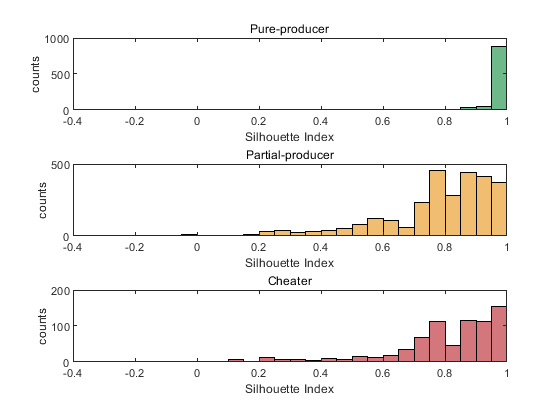

%ylim([0 1000]);
xlim([-0.4 1]);
ylabel('counts');
xlabel('Silhouette Index')
title('Pure-producer');
subplot(3,1,2)
histogram(s_partial,'FaceColor','#E89112',"BinWidth",0.05);
%ylim([0 1000]);
xlim([-0.4 1]);
ylabel('counts');
xlabel('Silhouette Index')
title('Partial-producer');
subplot(3,1,3)
histogram(s_cheater,'FaceColor','#B71C25',"BinWidth",0.05);
ylim([0 200]);
xlim([-0.4 1]);
ylabel('counts');
xlabel('Silhouette Index')
title('Cheater');

## Figure S2 

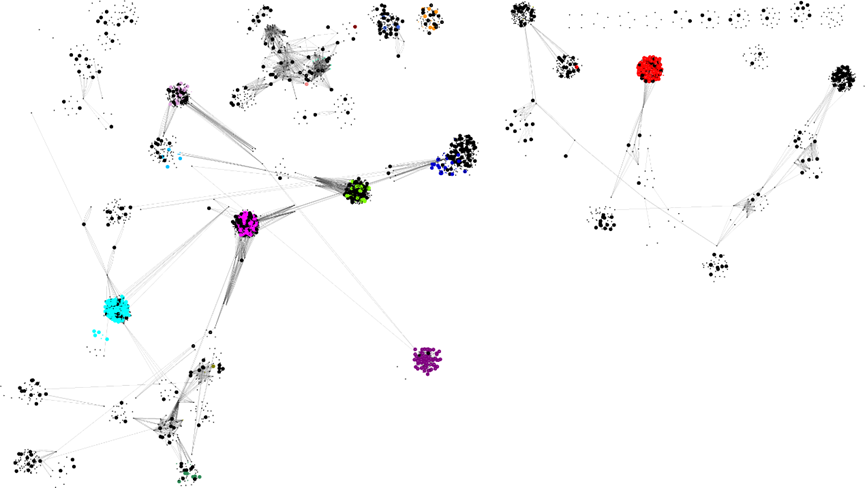

if  ~exist('./FigureS2_cytoscape/cyto_receptornodes_1.csv','file')
    load ./data/pickedrec_fpva.mat;
    load('./data/dist_toref.mat');
    load ./data/refreceptors.mat;
    refdistm_fpva=refdistm_fpva(:,cell2mat(rec.locinpickedrec_fpva));
    mindist_toref=mindist_toref(cell2mat(rec.locinpickedrec_fpva));
    
    mindist_groups=nan*zeros(totalgnum_new);
    mindistcarriers_abs=[];
    for g1=1:totalgnum_new
            members_1=find(recgroup_new==g1);
            for g2=(g1+1):totalgnum_new
                members_2=find(recgroup_new==g2);
                tempdistm=rec.seqdist678910(members_1,members_2);
                minv=min(tempdistm(:));
                
                mindist_groups(g1,g2)=minv;
                mindist_groups(g2,g1)=mindist_groups(g1,g2);
                
                [cand_1,cand_2]=find(tempdistm==minv);
                for k=1:length(cand_1)
                    mindistcarriers_abs=[mindistcarriers_abs;[members_1(cand_1(k)),members_2(cand_2(k)),minv]];
                end
            end
    end
    
    groupassigncolor=find(group_typebelong(1,:)>0);

    threshold=0.3;
    cytooutpath_recs=sprintf('./FigureS2_cytoscape/cyto_receptorsimilarity_%0.2f.csv',threshold);
    fid=fopen(cytooutpath_recs,'w+');
    fprintf(fid,'rec1,rec2,similarity,wb\n');
    for i=1:rec.datanum
        for j=1:(i-1)
            distv=rec.seqdist678910(i,j);
            if (distv<threshold)
                fprintf(fid,'%d,%d,%0.3f,%d\n',i,j,1-distv,0);
            end
        end
    end
    % add the connecting edge between different clusters
    for i=1:size(mindistcarriers_abs,1)
        distv=mindistcarriers_abs(i,3);
        if distv<0.4
            fprintf(fid,'%d,%d,%0.3f,%d\n',mindistcarriers_abs(i,1),mindistcarriers_abs(i,2),1-distv,1);
        end
    end
    
    for i=1:size(mindist_groups,1)
        distline=mindist_groups(i,:);
        distline(i)=nan;
        
        [values,order]=sort(distline);
        for j=1:2
            minv=values(j);
            if minv<0.5
                lines=find(sum(ismember(recgroup_new(mindistcarriers_abs(:,1:2)),[i,order(j)]),2)==2);
                for k=1:length(lines)
                    fprintf(fid,'%d,%d,%0.3f,%d\n',mindistcarriers_abs(lines(k),1),mindistcarriers_abs(lines(k),2),1-mindistcarriers_abs(lines(k),3),1);
                end
            end
        end
    end
    
    fclose(fid);
    
    
    
    cytooutpath_recnodes='./FigureS2_cytoscape/cyto_receptornodes_1.csv';
    fid=fopen(cytooutpath_recnodes,'w+');
    fprintf(fid,'rec,groupid,straintype,candself,nearesttype,color\n');
    for i=1:rec.datanum
        % gray for receptors in partial
        % black for receptors in cheater
        % colored for receptors in pure, by their groups
        straintype=rec.straintype(i);
        groupid=recgroup_new(i);
        if straintype==2
            colorcode=[1,1,1]*0;% partial
        elseif straintype==3
            colorcode=[72/255,72/255,72/255]*0;%cheater
        elseif straintype==1% groups in pure
            locingroupassigncolor=find(groupid==groupassigncolor);
            colorcode=colorgroups(locingroupassigncolor,:);
        else
            colorcode=[1,1,1];% nan
        end
        colorstr=rgb2hex(colorcode);
        
        if mindist_toref(i)<0.3
            [minv,refid]=min(refdistm_fpva(:,i));
            templist=strsplit(refreceptors.shortnames{refid},'|');
            nearesttype_str=templist{end};
            nearesttype_str=[nearesttype_str,'(',num2str(refreceptors.rectype(refid)),')'];
        else
            nearesttype_str='';
        end
        fprintf(fid,'%d,%d,%d,%d,%s,%s\n',i,groupid,straintype,pickedrec_fpva.candself(i),nearesttype_str,colorstr);
    end
    fclose(fid);
end
    